#    Computational Electromagnetics 

##                           Hw3

                 Mohammadreza Arani         :::::::::::::         810100511

                                                            1401/08/23 

## Extra Question:     

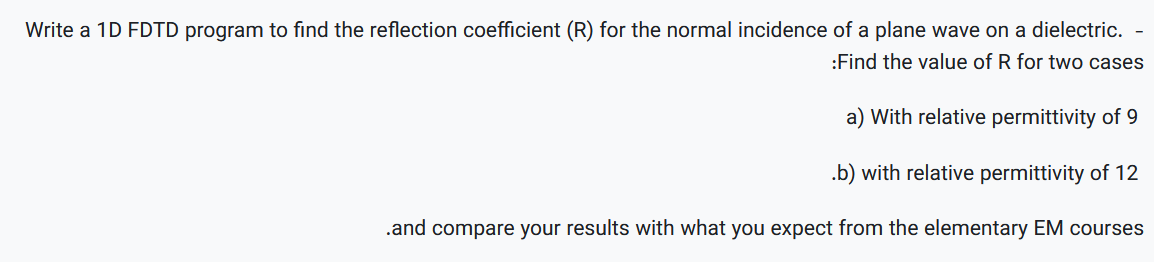

A plane Wave --> Ez , Hy --> going in +X direction 


clear; clc; close all; format compact



    IMAX = 19;
    NMAX=2; NNMAX =50; NHW =40; 
    DELTA = 3e-3; CL = 3.0e+08; F = 2.5e+09; % 2.5 GHz

%  Define Scatterer Dimensions:
   % OI = 19.5; OJ = 20.0; OK =19.0; RADIUS = 15.0;
    ER =[1.0;9.0] ;  % CONSTITUTIVE Parameters



    E0 = (1e-9)/(36*pi) ;
    SIG  = [0.1; 0.0 ];
    U0 = (1e-7)*4*pi ;
    DT = DELTA/(2*CL);
    R = DT/E0;

    RA = (DT^2)/(U0* E0*(DELTA^2));

    RB = DT / (U0*DELTA);


    TPIFDT = 2.0*pi*F*DT ;

    CA  = 1 - R*SIG./ER;
    CB =    RA./ER;
    CBMRB = CB/RB;


% ****************************************************************
% STEP # 1- Compute Media Parameters:
% ****************************************************************

x = 0:IMAX+1 ; % y = 0:JMAX+1 ; z=0:KMAX+1;

[Mx] =ndgrid(x) ;

EZ = zeros(IMAX+2, NMAX+1);
HY = EZ;

NN = 10
NN = 20
NN = 30
NN = 40
NN = 50


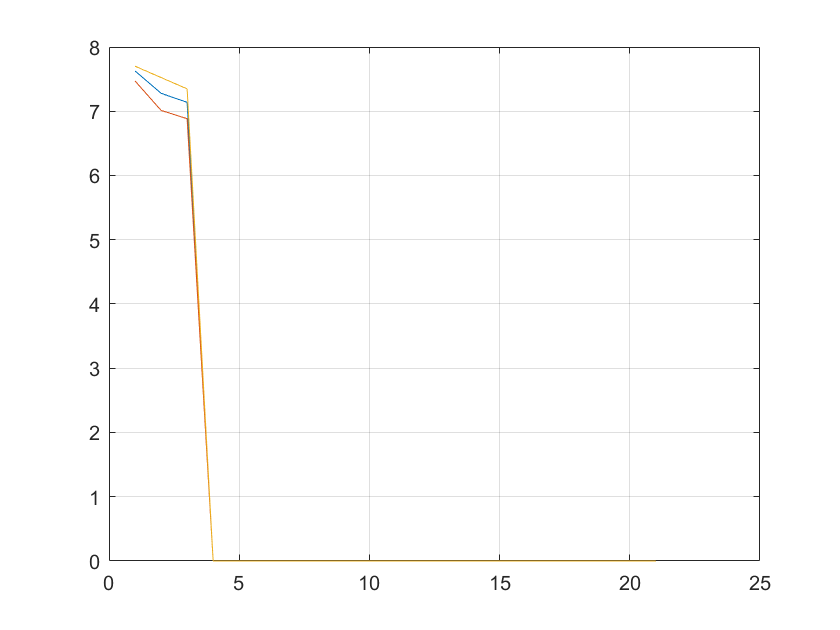



    NCUR =3;
    NPR1 = 2;
    NPR2 =1;
    IS = 2;

    for NN = 1:NNMAX % Time Loop
        if mod(NN,10)==0
            disp(['NN = ', num2str(NN)]) % Display Progress each 10 iterations passes
        end
        % Next time step - move indices up a notch.
        NPR2=NPR1;
        NPR1= NCUR;
        NCUR = mod(NCUR,3)+1;


                for I=0:IMAX % X Loop



                    if( 15<I )
                        CAM  = CA(2);
                       HY(I+1,NCUR) = HY(I+1,NPR1) + RB*( EZ(I+1+1,NPR1) - EZ(I+1,NPR1)   ) ;
                       EZ(I+1,NCUR) = CAM* EZ(I+1,NPR1) + CBMRB(2)* ( HY(I+1,NCUR)  ) ;
                    elseif(I==IS) % Apply Source Condition
                        EZ(I+1,NCUR)  = EZ(I+1,NCUR) + sin(TPIFDT * NN) ;
                    else
                   % --- HY generation:
                        CAM = CA(1);
                       HY(I+1,NCUR) = HY(I+1,NPR1) + RB*( EZ(I+1+1,NPR1) - EZ(I+1,NPR1)   ) ;
                       EZ(I+1,NCUR) = CAM* EZ(I+1,NPR1) + CBMRB(1)* ( HY(I+1,NCUR)  ) ;
                    end


                end
figure(1)
plot(EZ)
grid on
drawnow
    end % TIME LOOP

Reflection Coefficient can be obtained --> First we have Incident Wave  --> Ei

After This Algorithm we get to have Etotal!  --> which is Ei+ Escattered  -->

By having  Etotal - Ei = Escattered  --> R  =   Escattered / Ei !  --> The reflection coefficient!